% Step 1: Design Input Signal (PWM binary signal)
Ts = 0.1;                               % Sampling time (0.1 seconds)
t = 0 : Ts : 40;                        % 40 seconds duration, adjust as necessary
% 400 筆資料
u = square(2 * pi * 0.1 * t);           % Generate PWM signal (binary)
u = (u + 1)/2;                          % Normalize to 0 and 1

% Step 2: Perform Identification Experiment
% Assume the motor has an input-output relation, use synthetic data for demonstration
y = 0.5 * u + 0.05 * randn(size(u));    % Example output (with some noise)

% Use the first 400 data points for identification
u_id = u(1:400);
y_id = y(1:400);
data = iddata(y_id', u_id', Ts);        % Create identification data object

% Step 3: Continuous-Time System Identification using state-space model
% Using subspace method for system identification

% Identify a state-space model (order can be adjusted)
sys_ct = ssest(data, 2, 'Ts', 0);       % 2 states, continuous-time system

% Present the identified system
present(sys_ct);

sys_ct =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
                         x1                    x2
   x1  -102.6 +/- 7.643e+14   23.92 +/- 1.492e+14
   x2    -252 +/-  1.57e+15  -108.2 +/- 7.643e+14
 
  B = 
                        u1
   x1  16.71 +/- 1.839e+14
   x2  32.51 +/- 3.165e+14
 
  C = 
                        x1                   x2
   y1  18.01 +/- 3.867e+14  43.51 +/- 4.686e+14
 
  D = 
       u1
   y1   0
 
  K = 
                         y1
   x1  -2.698 +/- 2.936e+13
   x2  -4.892 +/- 4.768e+13
 
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 10
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                      
Termination condition: Maximum number of iterations reached..
Number of iterations: 20, N

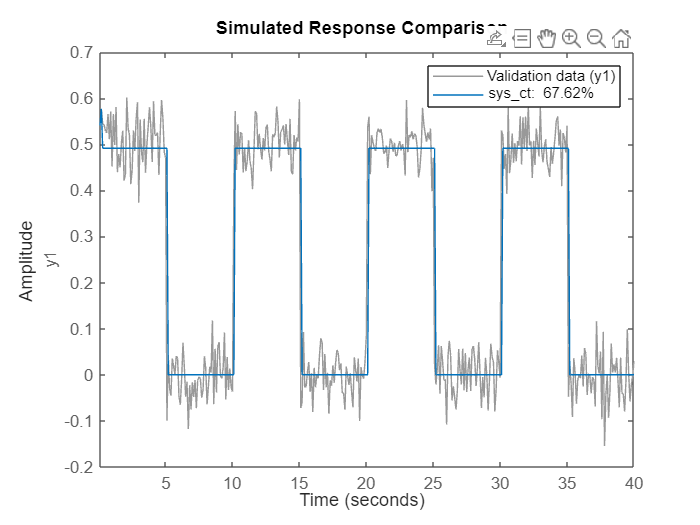


% Simulate the model
figure;
compare(data, sys_ct);